# Visualize Wuhan Virus Cases updated from Channel New Asia

From [https://www.channelnewsasia.com/news/topics/wuhan-virus,](https://www.channelnewsasia.com/news/topics/wuhan-virus,) extract wuhan virus data (table and chart)

a_tableinfo=webread('https://spreadsheets.google.com/feeds/list/1lwnfa-GlNRykWBL5y7tWpLxDoCfs8BvzWxFjeOZ1YJk/1/public/values?alt=json');
b_chartinfo=webread("https://spreadsheets.google.com/feeds/list/1NbedmkD3VpoP6Poc_1Xl-ElroXi08X5UyNBeyI1ts28/1/public/values?alt=json");

# Structure a_tableinfo & b_chartinfo to Table 

Structure it to table (Country, Updated Time and Confrimed Case)

% a_tableinfo
for i = 1:1:size(a_tableinfo.feed.entry,1)
    Country_a(i) = string(a_tableinfo.feed.entry(i).gsx_country.x_t);
    Updated_time_a(i) = string(a_tableinfo.feed.entry(i).updated.x_t);
    Confirmed_Case_a(i) = str2double(string(a_tableinfo.feed.entry(i).gsx_confirmedcases.x_t));
    Death_a(i) = str2double(string(a_tableinfo.feed.entry(i).gsx_reporteddeaths.x_t));
end
table_overall_a = table(Country_a',Updated_time_a',Confirmed_Case_a',Death_a');
table_overall_a.Properties.VariableNames = {'Country' 'Updated' 'Case' 'Death'};

%b_chartinfo
% a_tableinfo
for i = 1:1:size(b_chartinfo.feed.entry,1)
    Country_b(i) = string(b_chartinfo.feed.entry(i).gsx_place.x_t);
    Updated_time_b(i) = string(b_chartinfo.feed.entry(i).gsx_date.x_t);
    Confirmed_Case_b(i) = str2double(string(b_chartinfo.feed.entry(i).gsx_confirmedcases.x_t));
    Death_b(i) = str2double(string(b_chartinfo.feed.entry(i).gsx_reporteddeaths.x_t));
end

table_overall_b = table(Country_b',Updated_time_b',Confirmed_Case_b',Death_b');
table_overall_b.Properties.VariableNames = {'Country' 'Updated' 'Case' 'Death'};

%delete the row if updated time is unknown
table_overall_b(strcmp(table_overall_b.Updated,""),:)=[];

%Split into 2 table Case & Death associated with time
table_overall_b_Case=unstack(table_overall_b,"Case","Country");

table_overall_b_Case.Death =[];
table_overall_b_Death=unstack(table_overall_b,"Death","Country");

table_overall_b_Death.Case =[];

% Convert string to datetime
table_overall_b_Case.Updated = datetime(table_overall_b_Case.Updated,'InputFormat','MMM dd');
table_overall_b_Death.Updated = datetime(table_overall_b_Death.Updated,'InputFormat','MMM dd');

% Get the max value for same date (Some day reported the value multiple
% time)
variableName = table_overall_b_Case.Properties.VariableNames;
table_overall_b_Case=varfun(@max,table_overall_b_Case,'GroupingVariable','Updated');
table_overall_b_Case.GroupCount =[];
table_overall_b_Case.Properties.VariableNames = variableName;
table_overall_b_Death=varfun(@max,table_overall_b_Death,'GroupingVariable','Updated');
table_overall_b_Death.GroupCount = [];
table_overall_b_Death.Properties.VariableNames = variableName;

% Fill Missing Data
% fill missing data with previous value, if don't have previous value, fill
% it with zero
table_overall_b_Case = fillmissing(table_overall_b_Case,"previous");
table_overall_b_Case = fillmissing(table_overall_b_Case,"constant",0,'DataVariables',@isnumeric);
table_overall_b_Death = fillmissing(table_overall_b_Death,"previous");
table_overall_b_Death = fillmissing(table_overall_b_Death,"constant",0,'DataVariables',@isnumeric);

# Clear unimportant variables

clearvars Country_a Country_b Death_a Death_b table_overall_b Updated_time_b Updated_time_a Confirmed_Case_b Confirmed_Case_a i

# Visualize the Table form Data

table_overall_a

table_overall_a = 22×4 table
        Country                 Updated              Case    Death
    _______________    __________________________    ____    _____

    "China"            "2020-01-30T19:19:12.247Z"    7711     170 
    "Thailand"         "2020-01-30T19:19:12.247Z"      14     NaN 
    "Hong Kong "       "2020-01-30T19:19:12.247Z"      10     NaN 
    "Macau "           "2020-01-30T19:19:12.247Z"       7     NaN 
    "Taiwan"           "2020-01-30T19:19:12.247Z"       8     NaN 
    "United States"    "2020-01-30T19:19:12.247Z"       5     NaN 
    "Singapore"        "2020-01-30T19:19:12.247Z"      13     NaN 
    "Australia"        "2020-01-30T19:19:12.247Z"       7     NaN 
    "South Korea"      "2020-01-30T19:19:12.247Z"       6     NaN 
    "Japan"            "2020-01-30T19:19:12.247Z"      11     NaN 
    "Malaysia"         "2020-0

# Visualize the Chart Form Data

#### Figure 1 : StackedPlot of Wuhan Virus Confirmed Cases

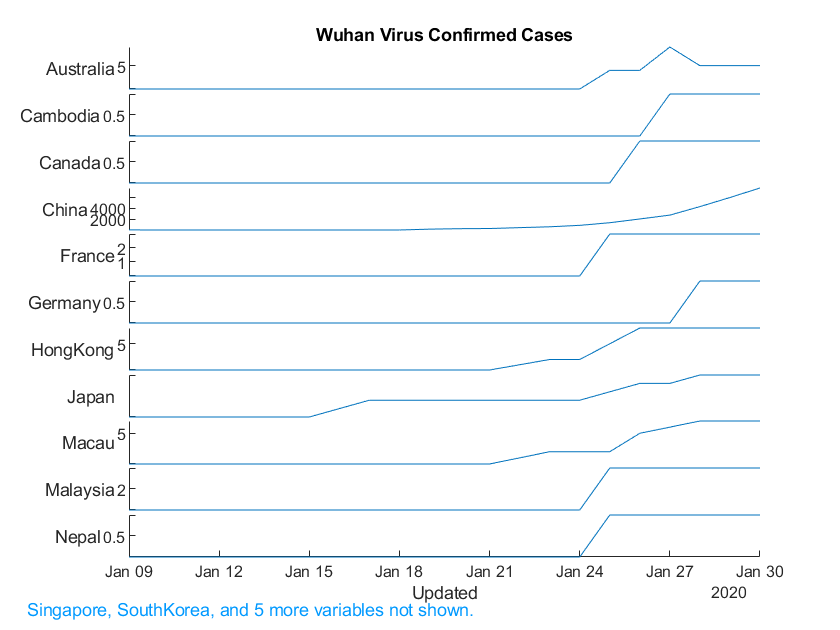

figure()
stackedplot(table2timetable(table_overall_b_Case));
title("Wuhan Virus Confirmed Cases")

#### Figure 2 : StackedPlot of Wuhan Virus Reported Death

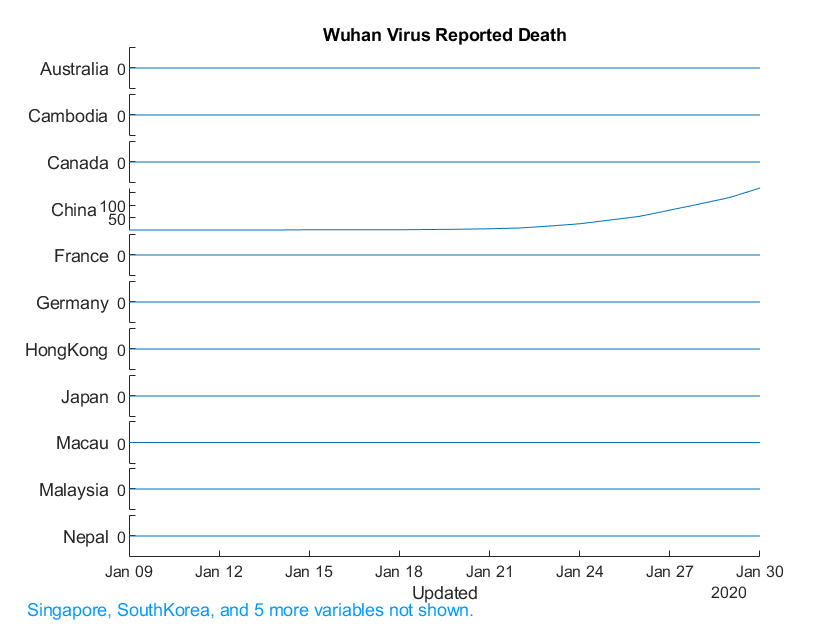

figure()
stackedplot(table2timetable(table_overall_b_Death));
title("Wuhan Virus Reported Death")

#### Figure 3 : China Confirmed Cases & Reported Death

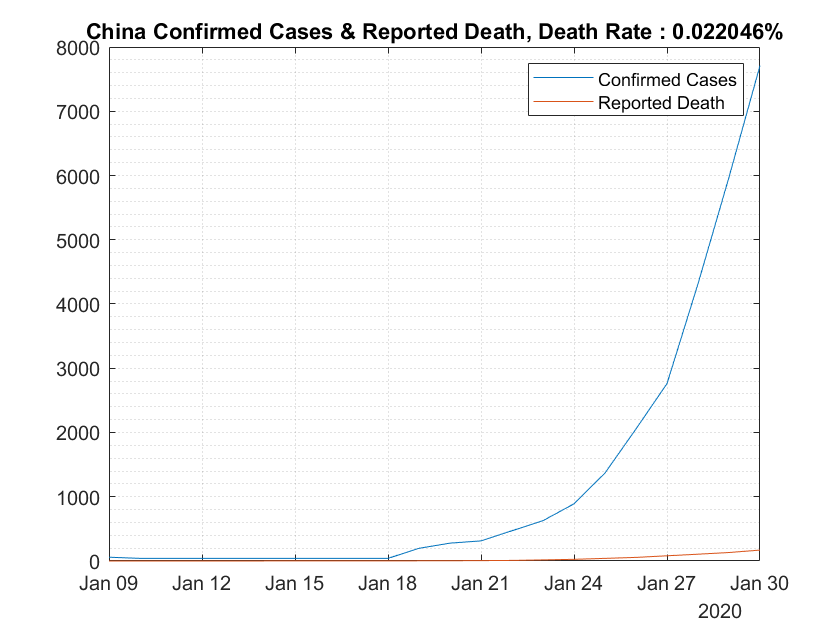

figure()
plot(table_overall_b_Case.Updated,table_overall_b_Case{:,"China"})
hold on
plot(table_overall_b_Death.Updated,table_overall_b_Death{:,"China"})
grid('minor')
legend('Confirmed Cases','Reported Death')
title(sprintf("China Confirmed Cases & Reported Death, Death Rate : %f%%",table_overall_b_Death{end,"China"}/table_overall_b_Case{end,"China"}))
hold off

#### Figure 4 : Other Countries (Other than China) Confirmed Cases & Reported Death

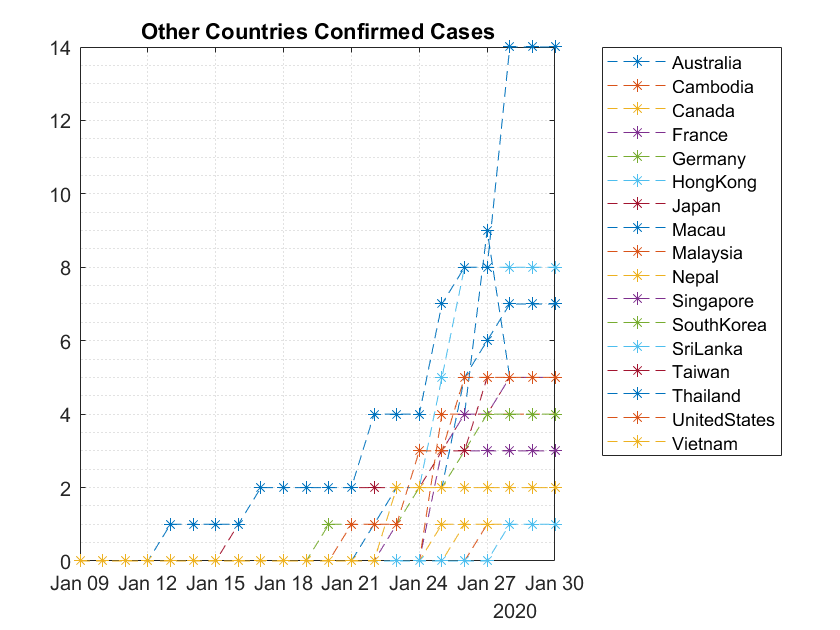

figure()
for i=1:1:length(variableName)-1
    if strcmp(table_overall_b_Case.Properties.VariableNames{i+1},'China') == false
        plot(table_overall_b_Case.Updated,table_overall_b_Case{:,i+1},'--*')
    end
hold on
end
grid('minor')
legend([variableName(2:4) variableName(6:end)],"Location","bestoutside")
title("Other Countries Confirmed Cases")
hold off

#### Figure 5 : Visualization of Geo Bubble Mapping

Get the latitude and longitude of countries from [https://developers.google.com/public-data/docs/canonical/countries_csv](https://developers.google.com/public-data/docs/canonical/countries_csv)

table_location = readtable('Geolocation.xlsx');
for i=1:1:height(table_overall_a)
    index=find(strcmp(strtrim(table_overall_a.Country(i)),strtrim(table_location.name)));
    latitude(i) = table_location.latitude(index);
    longitude(i) = table_location.longitude(index);
end
geotable = table(latitude',longitude',table_overall_a.Case);
geotable.Properties.VariableNames = {'latitude' 'longitude' 'Case'};
figure()
gb = geobubble(geotable,'latitude','longitude','SizeVariable','Case','Title','Geobubble Map For Wuhan Confirmed Cases')

gb =   GeographicBubbleChart with properties:

              Basemap: 'streets-light'
            MapLayout: 'normal'
          SourceTable: [22×3 table]
     LatitudeVariable: 'latitude'
    LongitudeVariable: 'longitude'
         SizeVariable: 'Case'
        ColorVariable: ''

  Show all properties


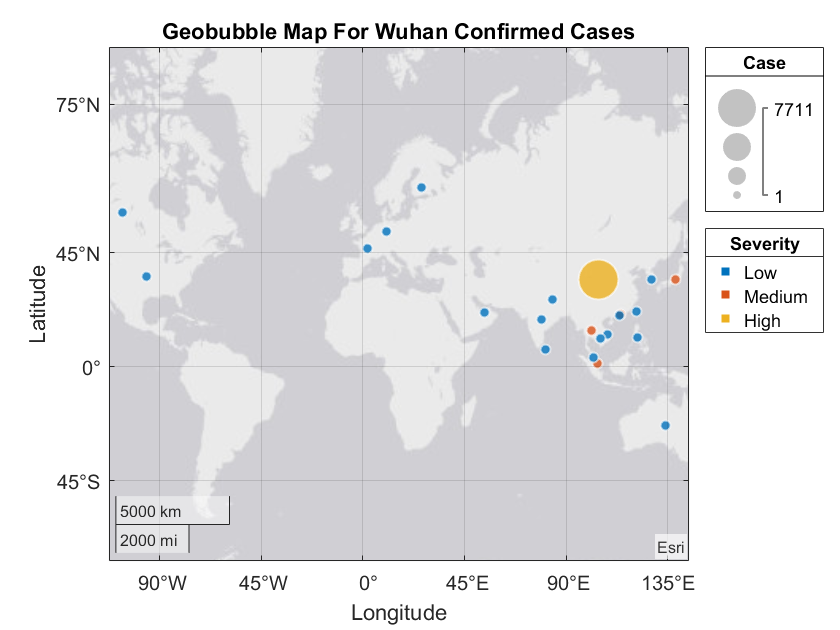

gb.SourceTable.Severity = discretize(table_overall_a.Case,[0 10 50 10000],...
                                 'categorical', {'Low', 'Medium', 'High'});
gb.ColorVariable = 'Severity';